根据CAS号，从数据库中找到对应物质的物性数据

以苯为例子，CAS = 71-43-2

CAS = '71-43-2';
C6H6 = Component(CAS);

- Pc，临界压力，Pa

Pc = C6H6.Pc

Pc = 4895000

- Tc，临界温度，K

Tc = C6H6.Tc

Tc = 562.0500

- Vc，临界体积，$\frac{m^3 }{\mathrm{kmol}}$

Vc = C6H6.Vc

Vc = 0.2560

- Zc，临界压缩因子， -

Zc = C6H6.Zc

Zc = 0.2680

- Tb，常压沸点温度，K

Tb = C6H6.Tb

Tb = 353.2400

- Ttriple，三相点温度，K

Ttriple = C6H6.Ttriple

Ttriple = 278.6800

- Ptriple，三相点压力，Pa

Ptriple = C6H6.Ptriple

Ptriple = 4.7642e+03

- Mw，摩尔质量，$\frac{\mathrm{kg}}{\mathrm{kmol}}$

Mw = C6H6.Mw

Mw = 78.1140

- $\omega \;$，偏心因子，-

Omega = C6H6.Omega

Omega = 0.2090

- ${H^m }_{\mathrm{form}}$ ，标准摩尔生成焓，$\frac{J}{\mathrm{kmol}}$

Hfrom = C6H6.Hform

Hfrom = 82880000

- ${G^m }_{\mathrm{from}}$ ，标准摩尔生成自由能，$\frac{J}{\mathrm{kmol}}$

Gform = C6H6.Gform

Gform = 129600000

- LiquidDensity，液体的密度，$\frac{\mathrm{kmol}}{m^3 }$

- $\rho_L =\frac{A}{B^{\left(1+{\left(1-\frac{T}{C}\right)}^D \right)} }$，$T\in \left\lbrack \mathrm{Tmin},\mathrm{Tmax}\right\rbrack \;$

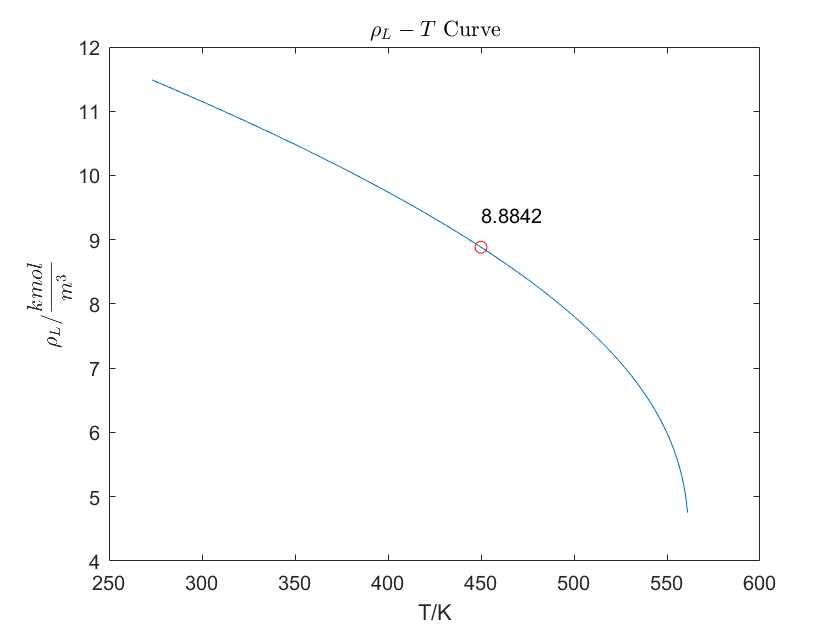


plot([C6H6.LiquidDensity(end-1):C6H6.LiquidDensity(end) ], C6H6.LiquidDensity_func( [C6H6.LiquidDensity(end-1):C6H6.LiquidDensity(end) ] ))
hold on
plot(450, C6H6.LiquidDensity_func(450),'or')
text(450, C6H6.LiquidDensity_func(450)+0.5, num2str(C6H6.LiquidDensity_func(450)) )
hold off
title('$${\rho_L-T}$$ Curve','Interpreter','latex')
xlabel('T/K')
ylabel('$${ \rho_L/ \frac{kmol}{m^3} }$$','Interpreter','latex')

function Property = Component(CAS)
    CAS = [CAS,'.json'];
    PropertyParameter = jsondecode(fileread(CAS));

    Property.CAS = PropertyParameter.CAS;
    Property.Ename = PropertyParameter.CompoundID;
    Property.StructureFormula = PropertyParameter.StructureFormula;

    % Pc,临界压力, Pa
    Property.Pc = str2double(PropertyParameter.CriticalPressure(1));
    % Tc,临界温度, K    
    Property.Tc = str2double(PropertyParameter.CriticalTemperature(1));
    % Vc, 临界体积, m3/kmol
    Property.Vc = str2double(PropertyParameter.CriticalVolume(1));
    % Zc, 临界压缩因子, -
    Property.Zc = str2double(PropertyParameter.CriticalCompressibility(1));
    % Tb, 常压沸点温度, K
    Property.Tb = str2double(PropertyParameter.NormalBoilingPointTemperature(1));
    % Ttriple, 三相点温度, K
    Property.Ttriple = str2double(PropertyParameter.TriplePointTemperature(1));
    % Ptriple, 三相点压力, Pa
    Property.Ptriple = str2double(PropertyParameter.TriplePointPressure(1));
    % Mw, 摩尔质量, kg/kmol
    Property.Mw = str2double(PropertyParameter.MolecularWeight(1));
    % Omega, 偏心因子, -
    Property.Omega = str2double(PropertyParameter.AcentricityFactor(1));
    % Hform, 标准摩尔生成焓, J/kmol
    Property.Hform = str2double(PropertyParameter.HeatOfFormation(1));
    % Gform, 标准摩尔生成自由能, J/kmol
    Property.Gform = str2double(PropertyParameter.GibbsEnergyOfFormation(1));
    
    % LiquidDensity, 液体的密度, kmol/m3
    % LiquidDensity_func, DIPPR函数
    equation = PropertyParameter.LiquidDensity(1);
    A = str2double(equation{1}.A);
    B = str2double(equation{1}.B);
    C = str2double(equation{1}.C);
    D = str2double(equation{1}.D);
    Tmin = str2double(equation{1}.Tmin);
    Tmax = str2double(equation{1}.Tmax);
    Property.LiquidDensity = [A, B, C, D, Tmin, Tmax];
    Property.LiquidDensity_func = @(T) A ./ B.^(1+ (1-T./C).^D);
end
